## Esercizio sulle scomposizioni matriciali

% Fisso il seed dei numeri casuali per la replicabilità dei risultati
% Ad esempio
rng(123)
% ovviamente il numero 123 è stato scelto a caso

% Generare una matrice di numeri casuali dalla distribuzione N(0,1)
% denominata X di dimensione nxp (ad esempio n=100 e p=5). 

n=100;
p=5;
X=randn(100,5);

% Calcolare il
% rango della matrice X tramite la funzione rank 
disp('Rango della matrice X')

Rango della matrice X


disp(rank(X))

          5.00




% Calcolare la matrice di covarianze S.
S=cov(X);
[V,La]=eig(S);

% Verificare la scomposizione spettrale della matrice 
%  S=V \Lambda V'.
% S ricostruita tramita la scomposizione spettrale


$$S=V \Lambda V'$$


Schk=V*La*V';
diffS=max(abs(S-Schk),[],'all');
assert(diffS<1e-12,"Matrice S non ricostruita correttamente")

%% Controllo dell'ortogonalità della matrice V
disp(V'*V)

          1.00         -0.00         -0.00         -0.00          0.00
         -0.00          1.00         -0.00          0.00         -0.00
         -0.00         -0.00          1.00          0.00         -0.00
         -0.00          0.00          0.00          1.00             0
          0.00         -0.00         -0.00             0          1.00




%% La somma degli autovalori coincide con la traccia
disp('Verifico che la traccia della matrice S è uguale alla somma dei suoi autovalori')

Verifico che la traccia della matrice S è uguale alla somma dei suoi autovalori


disp(['Traccia della matrice S=varianza totale=' num2str(trace(S))])

Traccia della matrice S=varianza totale=4.7321


disp(['Somma degli autovalori della matrice S=' num2str(sum(diag(La)))])

Somma degli autovalori della matrice S=4.7321



%% Il prodotto degli autovalori coincide con il determinante
detS=det(S);
proLa=prod(diag(La));
disp('Verifico che il prodotto degli autovalori della matrice S coincide con il determinante')

Verifico che il prodotto degli autovalori della matrice S coincide con il determinante


disp(['Determinante della matrice S=' num2str(detS)])

Determinante della matrice S=0.55907


disp(['Prodotto degli autovalori della matrice S=' num2str(proLa)])

Prodotto degli autovalori della matrice S=0.55907


%% Riordinare la matrici V e Lambda 
la=diag(La);
[~,indsor]=sort(la,'descend');
% Riordino le colonne della matrice V e La in modo tale che
% La(1,1) sia il grande autovalore e V(:,1) sia l'autovettore associato
% La(2,1) sia il secondo più grande autovalore e V(:,2) sia l'autovettore associato
V=V(:,indsor);
lasor=la(indsor);
La=diag(lasor);


Verificare tramite la funzione rank che la matrice pxp  


$$v_i v_i'$$


abbia rango 1, i=1, 2, ..., p 

% Controllo il rango della matrice
% v_i v_i' per un valore di i generico
i=2;
v2=V(:,i);
istringa=num2str(i);
disp(['Rango della matrice v_' istringa 'v_' istringa ''''])

Rango della matrice v_2v_2'


disp(rank(v2*v2'))

          1.00




% S ricostruita tramite la somma di p matrici
% quadrate ciascuna di rango 1
Schk1=zeros(p,p);
% S ricostruita tramite la somma di p matrici
% quadrate ciascuna di rango 1
for j=1:p
    Schk1=Schk1+La(j,j)*V(:,j)*V(:,j)';
end

diffS1=max(abs(S-Schk),[],'all');
assert(diffS1<1e-12,"Matrice S non ricostruita correttamente")


SCOMPOSIZIONE IN VALORI SINGOLARI

% Effettuare la scomposizione in valori singolari della matrice Xtilde

 
$$\tilde X= U  \Gamma   Vtramitesvd'$$


%% Scomposizione in valori singolari della matrice Xtilde
% Xtilde = matrice degli scostamenti dalla media
Xtilde=X-mean(X);

[U,Gam,Vtramitesvd]=svd(Xtilde,'econ');
Xtildechk=U*Gam*Vtramitesvd';
disp('Ricostruzione della matrice Xtilde')

Ricostruzione della matrice Xtilde


disp('Controllo che il massimo delle differenze tra X tilde e X tilde ricostruita in valore assoluto sia un numero piccolissimo')

Controllo che il massimo delle differenze tra X tilde e X tilde ricostruita in valore assoluto sia un numero piccolissimo


diffTraXtildeEXtildechk=max(max(abs(Xtilde-Xtildechk)));
assert(diffTraXtildeEXtildechk<1e-12,"Matrice Xtilde non ricostruita correttamente")

% Controllo che la matrice Vtramitesvd sia uguale (a meno del segno) alla
% matrice V ottenuta tramite la scomposizione spettrale della matrice S
disp('Matrice V')

Matrice V



disp(V)

          0.10          0.03         -0.28          0.59          0.75
          0.28         -0.27         -0.76         -0.51          0.10
          0.88         -0.26          0.39          0.04          0.01
         -0.04         -0.51         -0.30          0.59         -0.55
          0.37          0.77         -0.32          0.20         -0.35



disp('Matrice Vtramitesvd')

Matrice Vtramitesvd


disp(Vtramitesvd)

          0.10          0.03         -0.28         -0.59         -0.75
          0.28         -0.27         -0.76          0.51         -0.10
          0.88         -0.26          0.39         -0.04         -0.01
         -0.04         -0.51         -0.30         -0.59          0.55
          0.37          0.77         -0.32         -0.20          0.35




maxdiffTraLeDueV=max((abs(V)-abs(Vtramitesvd)),[],'all');
assert(maxdiffTraLeDueV<1e-12,"Le due matrici V e Vtramitesvd sono diverse")


% Verificare che (\Gamma/sqrt(n-1)).^2 = \Lambda dove \Lambda è la matrice
% degli autovalori ottenuta in precendenza tramite la scomposizione
% spettrale della matrice S



$$(\Gamma/\sqrt(n-1))^2 = \Lambda$$



% Verifica che (\Gamma/sqrt(n-1)).^2 = \Lambda
disp('(\Gamma/sqrt{ n-1})^2')

(\Gamma/sqrt{ n-1})^2


disp((Gam/sqrt(n-1)).^2)

          1.49             0             0             0             0
             0          1.11             0             0             0
             0             0          0.90             0             0
             0             0             0          0.68             0
             0             0             0             0          0.55



disp('Matrice \Lambda degli autovalori della matrice di covarianze')

Matrice \Lambda degli autovalori della matrice di covarianze


disp(La)

          1.49             0             0             0             0
             0          1.11             0             0             0
             0             0          0.90             0             0
             0             0             0          0.68             0
             0             0             0             0          0.55




% OSSERVAZIONE: nella scomposizione spettrale gli autovalori sono ordinati
% dal più piccolo al più grande, nella scomposizione in valori singolari i
% valori singolari (radici quadrate degli autovalori) sono ordinati dal più
% grande al più piccolo ecco perché  è stato necessario precedentemente
% effettuare il riordinamento degli autovalori


% Controllare che la matrice di dimensione nxp 



$$\gamma_i u_i v_i'$$


% abbia rango 1, i=1, 2, ..., p
% Osservazione: se voglio controllare che per ogni i il rango sia uguale ad
% 1 devo inserire l'assert dentro un ciclo for
disp('Rango della matrice di dimensione nxp: u_i v_i''')

Rango della matrice di dimensione nxp: u_i v_i'


for i=1:p
    ui=U(:,i);
    vi=V(:,i); % oppure vi=Vtramitesvd(:,i)
    istringa=num2str(i);
    disp(['Rango della matrice di dimensione nxp: u_' istringa 'v_' istringa ''''])
    disp(rank(ui*vi'))
end

Rango della matrice di dimensione nxp: u_1v_1'


          1.00



Rango della matrice di dimensione nxp: u_2v_2'


          1.00



Rango della matrice di dimensione nxp: u_3v_3'


          1.00



Rango della matrice di dimensione nxp: u_4v_4'


          1.00



Rango della matrice di dimensione nxp: u_5v_5'


          1.00



% Ricostruire la matrice Xtilde tramite la somma di p matrici di dimensioni nxp
% ciascuna di rango 1 
% $\tilde X = \sum_i=1^p \gamma_i u_i v_i'$



$$\tilde X = \sum_{i=1}^p \gamma_i u_i v_i'$$


Xtildechk1=zeros(n,p);

for j=1:p
    Xtildechk1=Xtildechk1+U(:,j)*Gam(j,j)*Vtramitesvd(:,j)';
end
disp('Controllo che il massimo delle differenze in valore assoluto sia un numero piccolissimo')

Controllo che il massimo delle differenze in valore assoluto sia un numero piccolissimo


disp(max(max(abs(Xtilde-Xtildechk1))))

          0.00




%% Calcolare la somma dei quadrati delle differenze che si ottengono quando
% la matrice Xtilde viene approssimata dalla matrice Xcappello
% Xcappello=$\sum_i=1^2 \gamma_i u_i v_i'$
% ossia dalla matrice di rango 2 contenente i due autovalori più grandi 

% Calcolo  Xcappello=\sum_i=1^2 \gamma_i u_i v_i'
Xcappello=zeros(n,p);
for j=1:2
    Xcappello=Xcappello+U(:,j)*Gam(j,j)*Vtramitesvd(:,j)';
end
% Calcolo la somma dei quadrati delle differenze tra la matrice Xtilde e la
% matrice Xcappello (in maniera non matriciale)
disp(sum(sum((Xtilde-Xcappello).^2)))

        211.02




% Calcolo la somma dei quadrati delle differenze tra la matrice Xtilde e la
% matrice Xcappello (in maniera matriciale tramite la traccia)
disp(trace((Xtilde-Xcappello)'*(Xtilde-Xcappello)))

        211.02




% Verifico che la somma dei quadrati delle differenze è uguale alla  somma
% dei quadrati dei valori singolari da 3 a p
disp(sum(diag(Gam(3:end,3:end)).^2))

        211.02




% La matrice Xcappello è la miglior rappresentazione di rango 2 della
% matrice Xtilde di partenza nel senso che se si sostituisce alla matrice
% Xcappello qualsiasi altra matrice di rango 2, la somma dei quadrati
% risulta maggiore.


## Esempio di applicazione della tecnica delle componenti principali

La zona B4:G13 del foglio dati del file aziende.xlsx contiene i dati di 6 indicatori rilevati su 10 aziende

ECON=economic profit = differenziale tra il rendimento del capitale investito ed il suo costo

CASH= cash flow sul fatturato in percentuale

COSVA = costo del lavoro sul valore aggiunto

ROE = return on equity

INDE =  indebitamento sul capitale proprio

FATT = fatturato

1) Creare e commentare il diagramma di dispersione tra le variabili CASH (asse x) e COSVA (asse y).

2) Calcolare la matrice di correlazione in formato table e la matrice dei diagrammi di dispersione con le rette per ogni coppia di variabili.

3) Ridurre le dimensioni tramite la tecnica delle componenti principali. Discutere se in questo caso è meglio operare sulle variabili originarie oppure sulle variabili standardizzate

Osservazione: i quesiti di seguito devono essere risolti inizialemente senza far ricorso alla routine pcaFS. Confrontare i risultati ottenuti manualemente con quelli che derivano dall'utilizzo di pcaFS 

4) Calcolare la quota di varianza spiegata dalle diverse componenti principali. Discutere il numero appropriato di dimensioni da considerare. Interpretare le componenti principali che vengono estratte. Calcolare le comunalità utilizzando solo le componenti principali che vengono estratte. Qual è l'unica variabile che viene spiegata poco?

Calcolare la lunghezza dei due semiassi principali dell'ellissoide che racchiude i punti nello spazio a 6 dimensioni.

5) Rappresentare graficamente le correlazioni tra le variabili originarie e le prime due componenti principali.

Commentare l'angolo tra FATT e COSVA

6) Costuire il biplot (utilizzando le due configurazioni descritte nel libro) e commentare i risultati ottenuti.

Come devono essere interpretati i punti che si trovano in direzione di una determinata freccia? e quelli che si trovano nella direzione opposta ad una determinata freccia? 

Cosa indicano i vettori  che presentano un angolo molto ridotto tra loro? 

Cosa indicano i vettori con un angolo vicino a 90 gradi? 

Cosa indicano i vettori i vettori con un angolo ridotto rispetto all'asse delle x (prima componente) oppure all'asse y (seconda componente) 

7)  Commentare nel biplot la posizione della PARMALAT

Xtable=readtable("aziende.xlsx","Sheet","dati","ReadRowNames",true);
X=Xtable{:,:};
nameXvars=Xtable.Properties.VariableNames;
p=size(X,2);

% Standardizzo i dati
Z=zscore(X);
% calcolo matrice di correlazione
R=corr(X);
% mostro la matrice di correlazione in formato table
Rtable=array2table(R,'RowNames',nameXvars,'VariableNames',nameXvars);
format bank
disp(Rtable)

             ECON     CASH     COSVA     ROE     INDE     FATT 
             _____    _____    _____    _____    _____    _____

    ECON      1.00     0.53    -0.22     0.82    -0.66    -0.08
    CASH      0.53     1.00    -0.61     0.82    -0.04    -0.39
    COSVA    -0.22    -0.61     1.00    -0.50    -0.28     0.50
    ROE       0.82     0.82    -0.50     1.00    -0.25    -0.24
    INDE     -0.66    -0.04    -0.28    -0.25     1.00    -0.01
    FATT     -0.08    -0.39     0.50    -0.24    -0.01     1.00



format short
% Correlazione molto elevata tra ECON e ROE

%% Autovettori e autovalori della matrice di correlazione
[V,La]=eig(R);
la=diag(La);
[~,indsor]=sort(la,'descend');
% Riordino le colonne della matrice V e La in modo tale che
% La(1,1) sia il grande autovalore e V(:,1) sia l'autovettore associato
% La(2,1) sia il secondo più grande autovalore e V(:,2) sia l'autovettore associato
V=V(:,indsor);
lasor=la(indsor);
La=diag(lasor);

%% CALCOLO COMPONENTI PRINCIPALI
% Calcolare la matrice che contiene le
% componenti principali (Y=Z V)
Y=Z*V;

% namePCS contiene la sequenza di etichette PC1, ..., PCp
namePCs=cellstr([repmat('PC',p,1) num2str((1:p)')]);
% Calcolo la quota di varianza spiegata da ciascuna CP
% autoval è una matrice di dimensione px3 che contiene
% Prima colonna: autovalori ordinati
% Seconda colonna: 100*autovalori/p
% Terza colonna: somma cumulata in percentuale
autoval=[lasor 100*(lasor)/p 100*cumsum(lasor)/p];
namecols={'Autovalori' 'Var_spiegata' 'Var_cum_spiegata'};
autovaltable=array2table(autoval,'RowNames', ...
    namePCs,'VariableNames',namecols);
disp(autovaltable)

           Autovalori    Var_spiegata    Var_cum_spiegata
           __________    ____________    ________________

    PC1       3.0263        50.438            50.438     
    PC2       1.6724        27.873            78.311     
    PC3      0.77074        12.846            91.157     
    PC4      0.31809        5.3014            96.458     
    PC5      0.17167        2.8612            99.319     
    PC6     0.040843       0.68071               100     



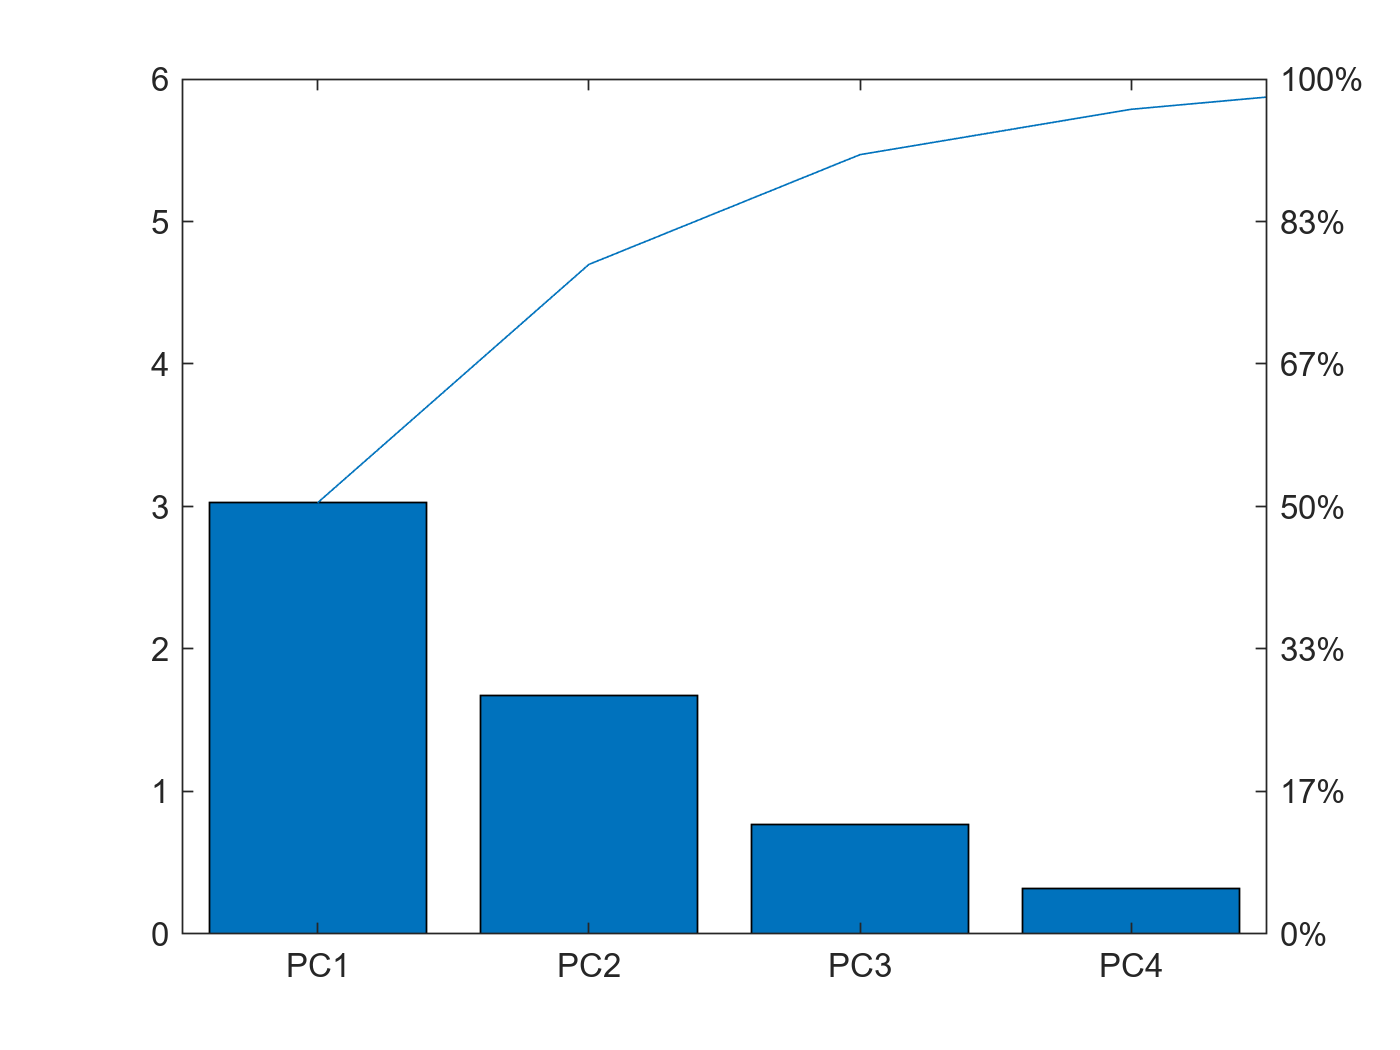

% Commento: tutti i diversi criteri di scelta della componenti (ad esempio 0.95^6=0.7351)
% segnalano che occorre estrarre 2 componenti.
% Perdita di informazione= 22 per cento circa

%% VISUALIZZAZIONE VARIANZA SPIEGATA TRAMITE DIAGRAMMA DI PARETO
figure
pareto(autoval(:,1),namePCs)
xlabel('Componenti principali')
ylabel('Varianza spiegata (%)')



%% INTERPRETAZIONE DELLE COMPONENTI
% MatrComp = matrice che contiene le correlazioni tra le variabili
% originarie e le prime due componenti principali (matrici di componenti).
MatrComp=V*sqrt(La);

% MatrComp ha dimensione $p \times p$. Nel nostro esempio 7*7;
% Ora la ridefinisco prendendo solo le correlazioni tra le variabili
% originarie e le prime due componenti principali
MatrComp=MatrComp(:,1:2);

%% Matrice di componenti in formato table

MatrCompt=array2table(MatrComp,"RowNames",nameXvars,"VariableNames",namePCs(1:2));
disp('Correlazioni tra le variabili originarie e le CP')

Correlazioni tra le variabili originarie e le CP


disp(MatrCompt)

               PC1         PC2   
             ________    ________

    ECON     -0.79785    -0.55243
    CASH     -0.88175     0.19971
    COSVA     0.65491    -0.61484
    ROE      -0.93394    -0.11954
    INDE      0.30039     0.83921
    FATT      0.46996    -0.48034



% Valori elevati della prima CP
% Aziende con basso economic profit,  basso cash flow, elevato costo del lavoro basso ROE 
% (e elevato fatturato).
% 

% La seconda CP è caratterizzata principalemnte dall'indebitamento e dal
% costo del lavoro Le aziende con Valori elevati della seconda CP
% presentano elevato indebitamento e basso costo del lavoro


%% SOMMA QUADRATI COLONNE DELLA MATRICE DI COMPONENTI

% La somma dei quadrati della colonna j della matrice di componenti è
% pari al j-esimo autovalore
j=1;
disp(['La somma dei quadrati della colonna ' num2str(j) ' della matrice di componenti'])

La somma dei quadrati della colonna 1 della matrice di componenti


sum(MatrComp(:,j).^2)

ans = 3.0263

disp(['è uguale all'' autovalore ' num2str(j) '=' num2str(lasor(j))])

è uguale all' autovalore 1=3.0263




% Calcolare la lunghezza dei due semiassi principali dell'ellissoide che
% racchiude i punti nello spazio a 6 dimensioni.
disp('Lunghezza dei primi due semiassi (valori singolari)')

Lunghezza dei primi due semiassi (valori singolari)


disp(sqrt(lasor(1:2)))

    1.7396
    1.2932





%% Visualizzazione grafica matrici di componenti
% Le label sull'asse x del grafico a barre sono i nomi delle variabili, il
% secondo argomento di categorical specifica che vogliano usare l'ordine
% delle labels specificato dentro varlabs e non l'ordine alfabetico
xlabels=categorical(nameXvars,nameXvars);

figure
for j=1:2
    subplot(2,1,j)
    b=bar(xlabels, MatrComp(:,j),'g');
    title(['Correlazioni con PC' num2str(j)])
    % xtips e ytips sono le coordinate numeriche dove inserire le etichette
    % del valore numerico sopra ogni barra
    xtips = b.XEndPoints;
    ytips = b.YEndPoints;
    barlabels = string(round(MatrComp(:,j),2));
    text(xtips,ytips,barlabels,'HorizontalAlignment','center',...
        'VerticalAlignment','bottom')
end

% Commento: l'angolo tra FATT e COSVA è molto basso quindi le due variabili sono molto correlate


%% COMUNALITA'
% Dalla matrice di componenti si calcolano le  comunalità (quote di
% varianza di ogni variabile spiegate dalla prime due componenti
% principali)
disp(['Comunalità: quote di varianza di ogni ' ...
    'variabile spiegate dalle prime due CP'])

Comunalità: quote di varianza di ogni variabile spiegate dalle prime due CP


Comu=sum(MatrComp.^2,2);

Comutable=array2table(Comu,'RowNames',nameXvars,...
    'VariableNames',{'Comunalità'});
disp(Comutable)

             Comunalità
             __________

    ECON      0.94174  
    CASH      0.81736  
    COSVA     0.80693  
    ROE       0.88653  
    INDE      0.79451  
    FATT      0.45158  



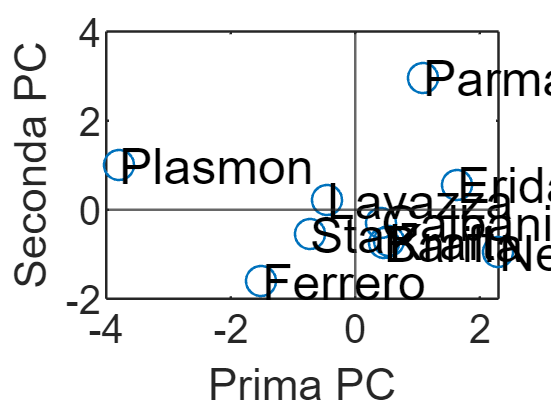


% FATT è la variabile spiegata meno, ECON quella spiegata di più

%% Rappresentazione delle correlazioni utilizzando la funzione quiver
% Rappresentazione delle frecce si possono tracciare utilizzando la funzione
% quiver
figure
zeroes = zeros(p,1);
% Frecce che partono dall'origine e arrivano fino a MatrComp
quiver(zeroes,zeroes,MatrComp(:,1),MatrComp(:,2))
% Label delle frecce
text(MatrComp(:,1),MatrComp(:,2),nameXvars,...
    'VerticalAlignment','bottom','HorizontalAlignment','center');
% Vengono aggiunti gli assi cartesiani
xline(0)
yline(0)
% Aggiunta delle label sugli assi
xlabel('Prima PC');
ylabel('Seconda PC');
% Stessa unità di misura per i due assi
axis equal


%% Rappresentazione nel piano cartesiano degli scores (non standardizzati)
figure
plot(Y(:,1),Y(:,2),'o')
xlabel('Prima PC');
ylabel('Seconda PC');
text(Y(:,1),Y(:,2),Xtable.Properties.RowNames)
% Vengono aggiunti gli assi cartesiani
xline(0)
yline(0)

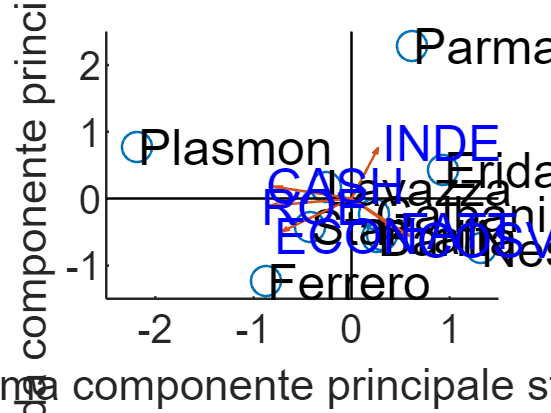


%% Calcolo delle componenti principali standardizzate
% Yst= componenti principali standardizzate cov(Yst) = matrice identità
Yst=Y*sqrt(inv(La));
% Rappresentazione nel piano cartesiano degli scores (standardizzati)
plot(Yst(:,1),Yst(:,2),'o')
xlabel('Prima PC');
ylabel('Seconda PC');
text(Yst(:,1),Yst(:,2),Xtable.Properties.RowNames)
% Vengono aggiunti gli assi cartesiani
xline(0)
yline(0)

%% Biplot (questa section non è riportata nel testo)
% Rappresentazione simultanea dei punti riga tramite gli score
% standardizzati e punti colonna tramite le correlazioni tra le variabili
% originarie e le componenti principali
close all
hold('on')
% Rappresentazione nel piano cartesiano dei punti riga tramite gli scores
% standardizzati
plot(Yst(:,1),Yst(:,2),'o')
xlabel('Prima componente principale stand. ');
ylabel('Seconda componente principale stand)');
text(Yst(:,1),Yst(:,2),Xtable.Properties.RowNames)
axislim=axis;
% Aggiungo l'asse x
line([axislim(1);axislim(2)], [0;0], 'Color','black');
% Aggiungo l'asse y
line([0;0],[axislim(3);axislim(4)], 'Color','black');

% Aggiunta delle frecce che rappresentano le correlazioni tra le variabili
% originarie e le componenti principali
zeroes = zeros(p,1);
quiver(zeroes,zeroes,MatrComp(:,1),MatrComp(:,2))

% vengono aggiunte le etichette con i nomi delle variabili
dx=0.01;
dy=0.01;
text(MatrComp(:,1)+dx,MatrComp(:,2)+dy,nameXvars,'Color','Blue');

% axis tight= Fit the axes box tightly around the data by setting the
% axis limits equal to the range of the data.
axis tight


% Commento: La Parmalat è nella direzione della variabile INDE di
% conseguenza è caratterizzata da un forte indebitamento.

% I punti che si trovano in direzione del vettore stanno a indicare che
% quelle aziende presentano valori alti di quella variabile (es. Parmalat è
% sulla direzione di INDE, e infatti ne presenta un valore molto alto). Al
% contrario, i punti che si trovano nella direzione opposta hanno valori
% bassi di quella variabile (es. Eridania ha un valore molto basso di
% ECON). I vettori con un angolo molto ridotto tra loro indicano una
% correlazione alta tra le varaibili corrispondenti (es. CASH e ROE). Al
% contrario, i vettori con un angolo vicino a 90 gradi indicano  le due
% corrispondenti variabili sono incorrelate (es. ECON e COSVA). I vettori
% con un angolo ridotto rispetto all'asse delle x (y) sono correlati
% (positivamente o inversamente in base al quadrante di appartenenza) con
% la prima (seconda) componente principale.
